# Angiogensis Stochastic Modeling

In this document we are going to present the model of angiogensis based on fractional stochastic differential equations.

For this document we are going to document step by step the definitions of the different parameters that construct this model.

## Parameter Definition

For this model we star by defining the state of the random algorithm in order to be repeateble

% by defining this function we are 
% setting a initial seed for the semi-random
% algorithm, this is going to help us 
% to repeat the script and have the same
% results
randn('state',5)

After running this function we start by defining the paremeters that are going to make this model.

First we define the parameters that are going to define the Brownian Path

T = 1 % time from 0 to 1

T = 1

N = 500 % there are going to be 500 steps

N = 500

dt = T/N % the discrete steps of the brownian

dt = 0.0020

         % path

Now we are going to define the parameters for the Stochastic Differential Equation that is going to define the model.

This model is based in the equation that Stokes & Lauffenburger (1991) developed. This SDE is


$$d\vec{v_i \left(t\right)} =-\beta \;\vec{\;v_i \left(t\right)} \textrm{dt}+\sqrt{\;\alpha }\;\vec{\;{\textrm{dW}}_i \left(t\right)} +\kappa \vec{\;\bigtriangledown a} \;\sin \;\left|\frac{\;\phi_i }{2}\right|\;\textrm{dt}$$


$\beta \;$: decay rate constant of the current velocity

$\alpha :\;$represents the magnitude of random fluctuations and their effect on cell movement

$\kappa :$ the chemotactic responsiveness

$\vec{\bigtriangledown a} :$ attractant concentration gradient

$\phi :$ angle between the direction the tip is moving and that towards the attractant source

$\vec{\;v_i } :$ velocity of the tip of the sprout

$\vec{\;W_i } :$ Brownian path of mean 0 and variance $\alpha \;$

% based on the empirical data extracted
% from stokes and lauffenburger
beta = 1/3 % h^-1

beta = 0.3333

alpha = 40 * 1/3 %µm^2 h-3

alpha = 13.3333

% we define this parameter arbitrarialy
kappa = 1/6 

kappa = 0.1667

## Brownian Path

Now we define the brownian path following the next equation


$$\begin{array}{l}
W_j =W_{j-1} +{\textrm{dW}}_j ,j=2,\ldotp \ldotp \ldotp ,N\\
W_1 =0\\
\textrm{dW}=\sqrt{\delta \;t}N\left(0,\alpha \right)
\end{array}$$


% we define the dW following the equation
% we definen 2 rows that contain N
% elements
% each row correspond with a spatial variable
dW = sqrt(dt)*randn(2,N)

dW =     0.0442   -0.0170   -0.0684    0.0496    0.0465   -0.0487   -0.0275   -0.0346   -0.0088   -0.0085   -0.0443   -0.0583   -0.0316    0.0074    0.0669    0.0747    0.0439    0.0333   -0.0026   -0.0585    0.0321   -0.0800    0.0100    0.0702   -0.0504   -0.0125   -0.0353    0.0310   -0.0471   -0.0572   -0.0494   -0.0078   -0.0128    0.0380   -0.0310   -0.0347   -0.0064    0.0112   -0.0595   -0.0113   -0.0437    0.1002   -0.0171   -0.0045   -0.0458    0.0085   -0.0142   -0.0161   -0.0456   -0.0499
    0.0116    0.0077    0.0000   -0.0466   -0.0251    0.0133   -0.0515    0.0160   -0.0159    0.0251   -0.0470    0.0581   -0.0179    0.0093    0.0258   -0.0125   -0.0325   -0.0248    0.0386   -0.0310   -0.0246    0.0612    0.0639    0.0660   -0.0498    0.0442   -0.0492   -0.1576   -0.0210    0.0415   -0.0038   -0.0648    0.0136    0.0502   -0.0361   -0.0513    0.0061    0.0044   -0.0332    0.1071   -0.0024   -0.0499    0.0001    0.0246   -0.0065    0.0007   -0.0397   -0.0254   -0.0166    

% Now we define the brownian path by the 
% comulative sum of dW 
W = cumsum(dW)

W =     0.0442   -0.0170   -0.0684    0.0496    0.0465   -0.0487   -0.0275   -0.0346   -0.0088   -0.0085   -0.0443   -0.0583   -0.0316    0.0074    0.0669    0.0747    0.0439    0.0333   -0.0026   -0.0585    0.0321   -0.0800    0.0100    0.0702   -0.0504   -0.0125   -0.0353    0.0310   -0.0471   -0.0572   -0.0494   -0.0078   -0.0128    0.0380   -0.0310   -0.0347   -0.0064    0.0112   -0.0595   -0.0113   -0.0437    0.1002   -0.0171   -0.0045   -0.0458    0.0085   -0.0142   -0.0161   -0.0456   -0.0499
    0.0558   -0.0093   -0.0684    0.0030    0.0214   -0.0354   -0.0790   -0.0185   -0.0247    0.0165   -0.0913   -0.0002   -0.0495    0.0167    0.0927    0.0622    0.0114    0.0085    0.0360   -0.0895    0.0075   -0.0188    0.0739    0.1363   -0.1002    0.0317   -0.0845   -0.1267   -0.0681   -0.0157   -0.0533   -0.0726    0.0008    0.0881   -0.0671   -0.0860   -0.0002    0.0156   -0.0927    0.0958   -0.0462    0.0503   -0.0170    0.0201   -0.0523    0.0093   -0.0539   -0.0415   -0.0621    0

Now we plot the brownian walk for the x variable and the y variable to see if it make sense

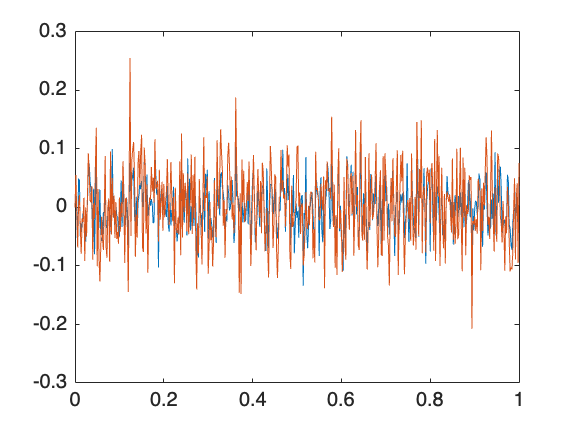

plot([0:dt:T],[0,W(1,:)]), hold on
plot([0:dt:T],[0,W(2,:)]), hold off

## Begining of the modeling

To solve the stochastic differential equation model we define the following L interger and stepsize $\Delta \;t=R\delta \;t$

R = 4;
Dt = R*dt;
L = N/R;

We initialize the solution vector

Xem = zeros(2,L); % first x
                  % second y
Vem = zeros(2,L);


Initialize the first point

Xzero = [0;0];
Xtemp = Xzero;
Vzero = [0;0];
Vtemp = Vzero;

And we initialize the first angles

theta = pi/2;
phi = pi/2;

We define the algorithm to calculate the $\vec{\;\Delta \;a}$

We define the gradient of attractant as


$$a=\frac{\;L}{1+b*\exp \left(-c*y\right)}$$



$$\Delta \;a=\left(0,\frac{\;L*b*c\;*\exp \left(-c*y\right)}{\left(1+b*{\left.\exp \left(-\mathrm{cy}\right)\right)}^2 \right.}\right)$$


These equations have been implemented in the functions that are in the folder functions

addpath("angiogenesis_model/functions/")

The paremeters for the equation for the attractant are

a = 5;
b = 10^5;
c = 0.3;
da = []


da =

     []



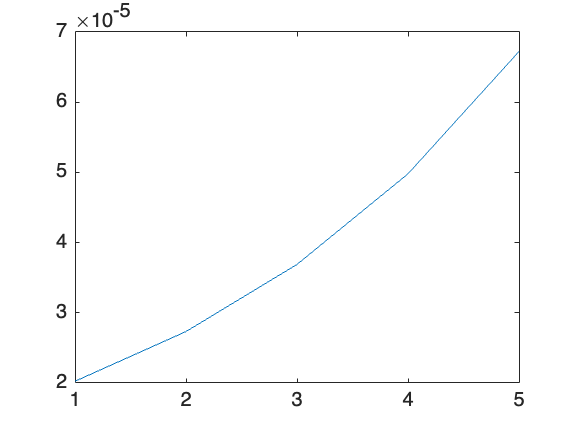

for i = 1:5
    da(i) = d_logistic_decay(a,b,c,i);
end
plot([1:5],da(:))

We beging the for loop for the model

for j = 1:L
    winc = sum(dW(:,R*(j-1)+1:R*j),2);
    DA = d_logistic_decay(a,b,c,Xem(2,j));
    Vtemp = Vtemp + (-beta * Vtemp + kappa * DA + sin(abs(phi/2)))*Dt + sqrt(alpha)*winc;
    Vem(:,j) = Vtemp;
    Xtemp = Xtemp + Vtemp * Dt;
    Xem(:,j) = Xtemp;
    if j ~= 1
        xj = Xem(1,j);
        yj = Xem(2,j);
        xj_1 = Xem(1,j-1);
        yj_1 = Xem(2,j-1);
        theta = atan((yj-yj_1)/(xj-xj_1));
        phi = calculate_phi( xj, yj , xj, yj+1, theta);
    end 
end

We see the array of solutions for the position

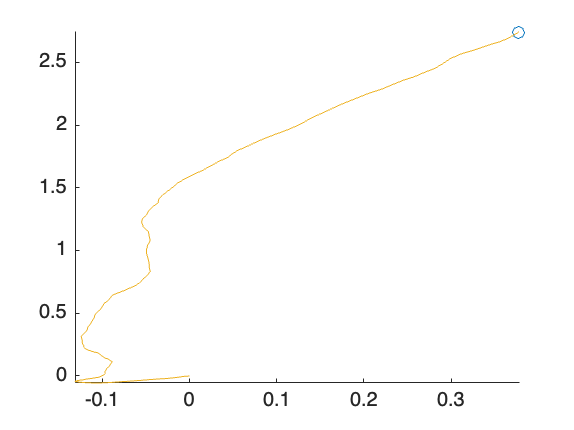

comet(Xem(1,:),Xem(2,:))